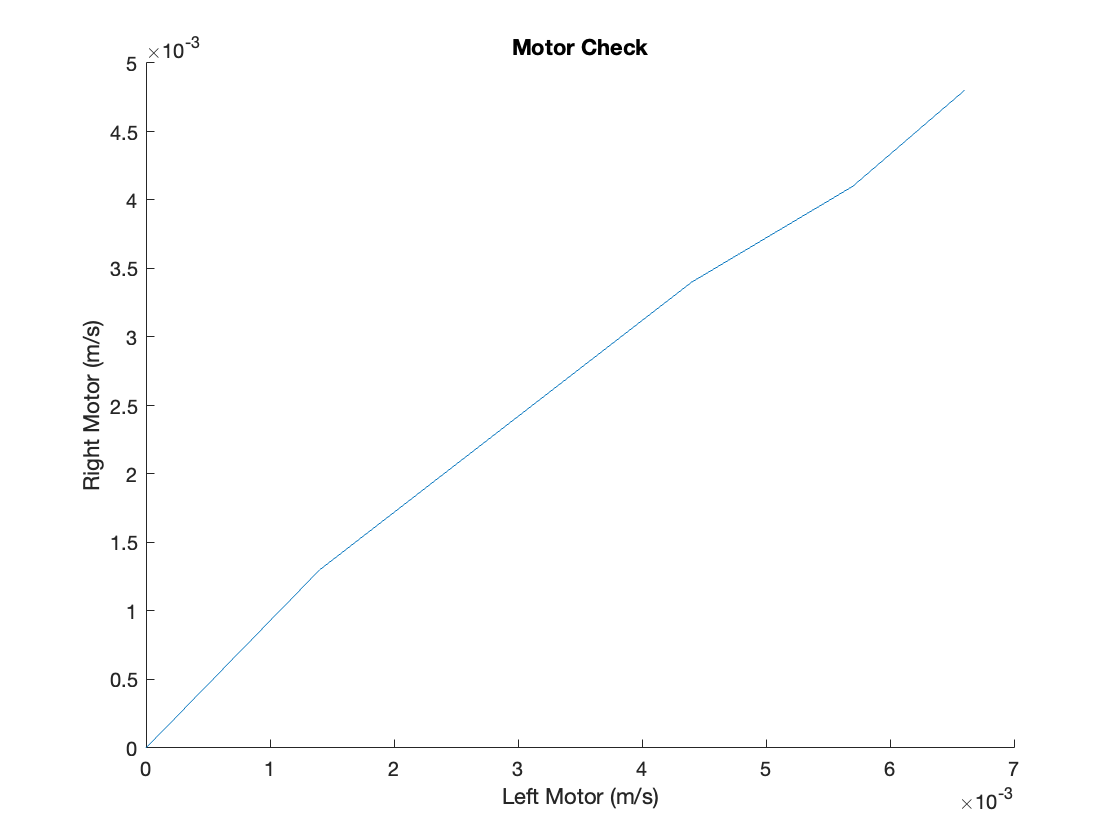

% Checking if motors have same speed

clear
load Data/calibration_first_run.mat

sample_limit = 5;                                               % Max limit of valid data
left_motor = calibration_first_run(1:sample_limit,1) / 100;
right_motor = calibration_first_run(1:sample_limit,2) / 100;

hold on 
title("Motor Check")
xlabel("Left Motor (m/s)")
ylabel("Right Motor (m/s)")
plot(left_motor, right_motor)

hold off 

p = polyfit(left_motor, right_motor, 1);
 
cali_cruve_slope = p(1);
cali_cruve_y_intercept = p(2);

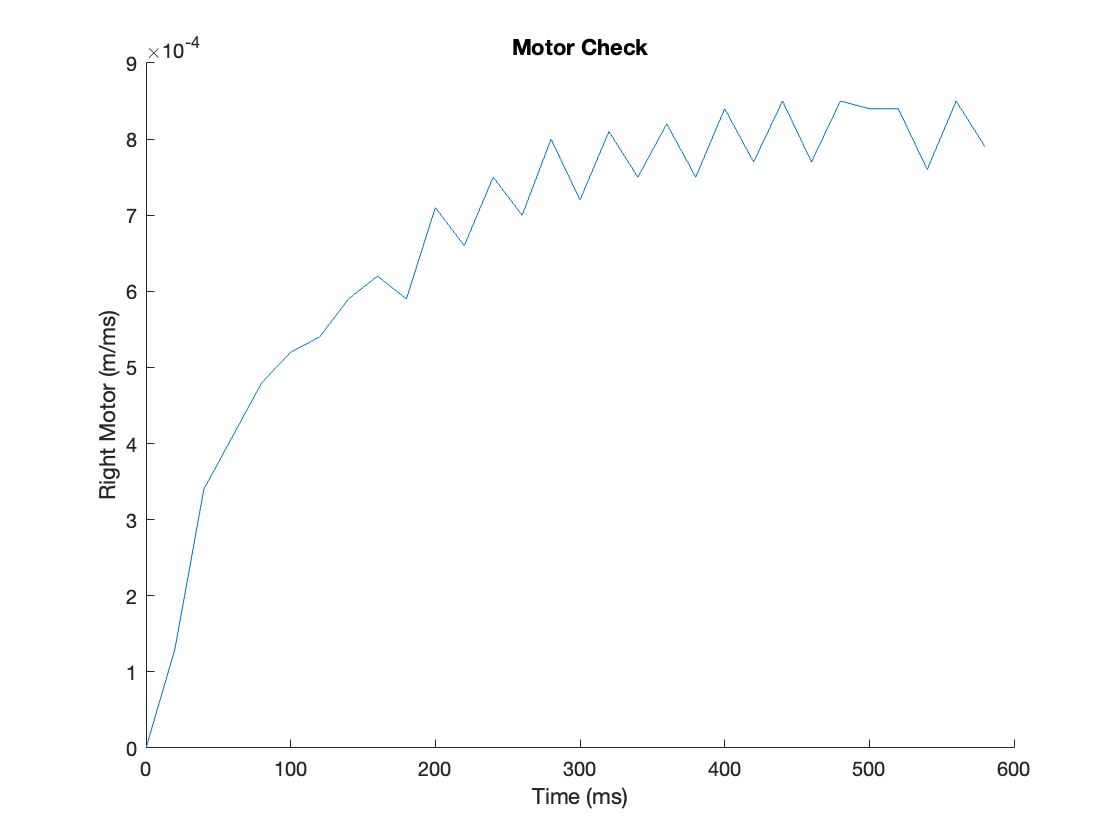

% Part A
clf
time_sample = 30;
time_interval = [0:20:(20*(time_sample-1))]';
right_motor = calibration_first_run(1:time_sample,2) / 1000;

hold on
title("Motor Check")
xlabel("Time (ms)")
ylabel("Right Motor (m/ms)")
plot(time_interval, right_motor)


%{

General model Exp2:
     f(x) = a*exp(b*x) + c*exp(d*x)
Coefficients (with 95% confidence bounds):
       a =    0.001019  (0.0003817, 0.001656)
       b =  -0.0003356  (-0.001319, 0.0006473)
       c =  -0.0009306  (-0.001537, -0.0003241)
       d =   -0.006074  (-0.01037, -0.001782)

Goodness of fit:
  SSE: 5.65e-08
  R-square: 0.9571
  Adjusted R-square: 0.9521
  RMSE: 4.661e-05

%}

% How to find tau and K? 

a = 0.001019;
b = -0.0003356;
c = -0.0009306;
d = -0.006074;

syms k tau x

equation_1 = a*exp(b*x) + c*exp(d*x);
equation_2 = k*(1-exp(-x/tau));

systems_equ = equation_1 == equation_2;

%systems_equ = [a*exp(b*x) + c*exp(d*x) == 0, k*(1-exp(-x/tau)) == 0]

S = solve(systems_equ, [k tau])

S = struct with fields:
      k: [1×1 sym]
    tau: [1×1 sym]



e1 = subs(equation_2,S)

$$e1 = \frac{1174827013194377\,{\mathrm{e}}^{-\frac{3095363655568463\,x}{9223372036854775808}}}{1152921504606846976}-\frac{4291635008748527\,{\mathrm{e}}^{-\frac{7002845218981989\,x}{1152921504606846976}}}{4611686018427387904}$$